# **SamSim simulation tool**

`Author: Samer A. Mohamed (https://github.com/SamMans) `

`Powered by: ASmarine`

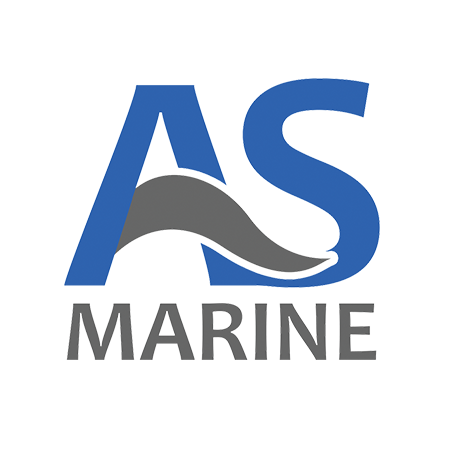

close
clear
clc

**Select AUV model:**

model = "Bolt";

**Enter desired simulation time (in seconds):**

Sim_Time = 80;

**Enter controller sampling time (in seconds, must be multiples of 0.05):**

dT = 0.1;
if(rem(dT, 0.05) ~= 0)
    error("Sampling times must be multiples of 0.05");
end

**Enter desired pose (in meters for linear motion and rad for rotational motion):**

X = 0; Y = 0;
Z = 1; Yaw = 0;

**Do you wish to record a video?**

Video = "No";

**Run simulation:**

 

% Author: Samer A. Mohamed (https://github.com/SamMans) 
% This script is used to run the AUV simulation
import java.util.*;

% Initial conditions
n = zeros(1, 6); %--> Initial global pose (1*6 vector)

% Create drone and control objects
AUV_1 = AUV(model, n, dT); %--> AUV object

% Create a controller object
C = Control_SMC_MPC(getsens(AUV_1), dT)

C =   Control_SMC_MPC with properties:

                dT: 0.1000
              Tlim: 10
               taw: [0 0 0 0 0 0 0 0]
                 n: [0 0 9.7390e-04 0 0 0]
                 v: [0 0 0 0 0 0]
    eta_tilde_prev: [3×1 double]
                 t: 0
                Sd: [3×1 double]
         S_eta_int: [3×1 double]
                tb: []
                j0: []
                j1: []
            s_prev: [0 0 0]
                 m: 13.5000
                Iz: 0.3700
            Xu_dot: 6.3570
            Yv_dot: 7.1210
            Nr_dot: 0.2215
                Xu: 13.7000
                Yv: 0
                Nr: 0
                Du: 141
                Dv: 217
                Dr: 1.5000
                 T: 1.5000
                 N: 15
            Tx_max: 50
            Ty_max: 5
            Mz_max: 50
              args: [1×1 struct]
                 Q: [6×6 double]
                 R: [3×3 double]
     

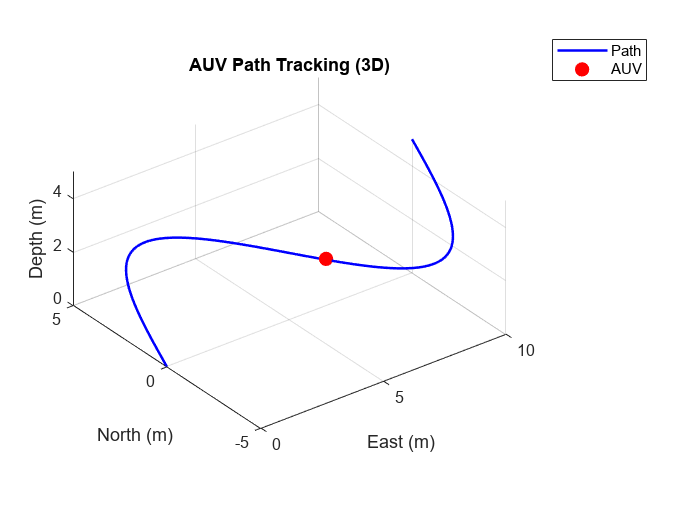


******************************************************************************
This program contains Ipopt, a library for large-scale nonlinear optimization.
 Ipopt is released as open source code under the Eclipse Public License (EPL).
         For more information visit http://projects.coin-or.org/Ipopt
******************************************************************************



% pose tracking
x = (0:0.1:10)';
y = 5*sin( 2 * pi * 0.1* x);
z = (0:0.05:5)';
path_points = [x,y,z];  % Straight-line path

% Initial and desired states
C = C.set_path(path_points);

% Create an empty stack for state history
history_stack = Stack();

tic
% Run model
states = getstate(AUV_1);
history_stack.push([states(1:12), 1500 * ones(1, 8), states(end)]);
t_last = 0; %--> Last recorded time
while(gettime(AUV_1) < Sim_Time)
    % Controller computes pwm values
    thres = ceil(t_last/dT) * dT; %--> Controller activation threshold
    % if (gettime(AUV_1) > 40)
    %     Z=3;
    % end

    if((t_last < thres && gettime(AUV_1) >= thres) || gettime(AUV_1) == 0)
        [C, PWM] = Actuate(C, getsens(AUV_1), [X, Y, Z, Yaw]); %--> Control function
    end
    t_last = gettime(AUV_1); %--> Update recorded time

    % Update AUV states
    AUV_1 = Solve(AUV_1, PWM);

    % Update history
    states = getstate(AUV_1);
    history_stack.push([states(1:12), PWM, states(end)]);
end

disp("Simulation run time is: " + toc + " seconds") 

% Get simulation history in matrix format (Java stack -> Matlab matrix)
history = zeros(history_stack.size(), 21);
for i = size(history, 1) : -1 : 1
    history(i, :) = history_stack.pop().';
end

% Produce plots
% Pose (X vs. Y)
Sz = 330; %--> Figure size
figure
hold on

% Plot path_points only if it exists
if exist('path_points', 'var')
    plot(path_points(:,1), path_points(:,2), 'r--', 'LineWidth', 2)  % Reference path
end

% Plot quiver arrows
qv_plot = history(1:round(size(history, 1)/50):end, :);
quiver(qv_plot(1:end-1, 1), qv_plot(1:end-1, 2), ...
       qv_plot(2:end, 1) - qv_plot(1:end-1, 1), ...
       qv_plot(2:end, 2) - qv_plot(1:end-1, 2), 'b')

% Annotation (optional, currently does nothing)
annotation('textbox', [.0 .0 .0 1.0], ...
    'EdgeColor', 'none', 'FontSize', 18, 'FontWeight', 'bold')

xlabel('X (m)', 'FontSize', 12, 'FontWeight', 'bold', 'Color', 'k')
ylabel('Y (m)', 'FontSize', 12, 'FontWeight', 'bold', 'Color', 'k')
set(gca, 'FontWeight', 'bold', 'FontSize', 18)
set(gcf, 'Units', 'points', 'Position', [0, 0, Sz, Sz])
set(gcf, 'Color', 'w')

% Add legend dynamically
legend_entries = {};
if exist('path_points', 'var')
    legend_entries{end+1} = 'Reference Path';
end
legend_entries{end+1} = 'Trajectory';
legend(legend_entries, 'Location', 'best')

% Pose vs. time
Y_axis = ["X (m)", "Y (m)", "Z (m)", "Roll (rad)", "Pitch (rad)", "Yaw (rad)"]; %--> Y axis labels 
for i = 1 : 6
    figure
    plot(history(:, end), history(:, i), 'r', 'LineWidth', 2)
    annotation('textbox', [.0 .0 .0 1.0], ...
    'String', char('a' + i - 1), 'EdgeColor', 'none','FontSize', 18, 'FontWeight', 'bold')
    xlabel('Time (sec.)','FontSize', 12, 'FontWeight', 'bold', 'Color', 'k')
    ylabel(Y_axis(i), 'FontSize', 12, 'FontWeight', 'bold', 'Color', 'k')
    set (gca, 'fontweight', 'bold', 'FontSize', 18) 
    set(gcf,'units','points','position',[.0, .0, Sz, Sz])
    set(gcf,'color','w');
end

% Velocity vs. time
Y_axis = ["Surge (m/s)", "Sway (m/s)", "Heave (m/s)", ...
    "About surge (rad/s)", "About sway (rad/s)", "About heave (rad/s)"]; %--> Y axis labels 
for i = 7 : 12
    figure
    plot(history(:, end), history(:, i), 'g', 'LineWidth', 2)
    annotation('textbox', [.0 .0 .0 1.0], ...
    'String', char('a' + i - 7), 'EdgeColor', 'none','FontSize', 18, 'FontWeight', 'bold')
    xlabel('Time (sec.)','FontSize', 12, 'FontWeight', 'bold', 'Color', 'k')
    ylabel(Y_axis(i - 6), 'FontSize', 12, 'FontWeight', 'bold', 'Color', 'k')
    set (gca, 'fontweight', 'bold', 'FontSize', 18) 
    set(gcf,'units','points','position',[.0, .0, Sz, Sz])
    set(gcf,'color','w');
end

% PWM vs. time
Y_axis = ["PWM 1 (us)", "PWM 2 (us)", "PWM 3 (us)", ...
    "PWM 4 (us)", "PWM 5 (us)", "PWM 6 (us)", ...
    "PWM 7 (us)", "PWM 8 (us)"]; %--> Y axis labels 
for i = 13 : 20
    figure
    plot(history(:, end), history(:, i), 'k', 'LineWidth', 2)
    annotation('textbox', [.0 .0 .0 1.0], ...
    'String', char('a' + i - 13), 'EdgeColor', 'none','FontSize', 18, 'FontWeight', 'bold')
    xlabel('Time (sec.)','FontSize', 12, 'FontWeight', 'bold', 'Color', 'k')
    ylabel(Y_axis(i - 12), 'FontSize', 12, 'FontWeight', 'bold', 'Color', 'k')
    set (gca, 'fontweight', 'bold', 'FontSize', 18) 
    set(gcf,'units','points','position',[.0, .0, Sz, Sz])
    set(gcf,'color','w');
end

% Run simulation
% Run simulink
if(Video == "Yes")
    % Video duration
    dur_vid = gettime(AUV_1);

    % State feed to visualization 
    NNx = [history(:, end), history(:, 1)]; NNy = [history(:, end), history(:, 2)];
    NNz = [history(:, end), history(:, 3)]; NNphi = [history(:, end), history(:, 4)];
    NNtht = [history(:, end), history(:, 5)]; NNeps = [history(:, end), history(:, 6)];

    % Run simulation
    sim("test_env.slx");

end